# Influence of porosity on material properties

### Material parameters


f_p = linspace(0, 100, 1e4); % Porosity, %
E_0 = 3e9; % Young's modulus, Pa
rho_0 = 1190; % Density, kg/m^3
epsilon_0 = 3; % Relative permittivity
p_c = 0.45; % 
f = 1.43;
beta = [0.2, 1, 3]';


### Calculation

Mechanical properties

f_p = f_p/100;
E = E_0*(1-min(f_p,p_c-1e-2)/p_c).^f;


Electrical properties

e_air = 1.00058;
epsilon = epsilon_0*(e_air+beta*f_p*(e_air-epsilon_0)+beta*epsilon_0)./(e_air-f_p*(e_air-epsilon_0)+beta*epsilon_0);


### Illustration

Mechanical properties

f_p = f_p*100;

fig = figure;
plot(f_p, E/1e9, 'LineWidth',3)
xlabel('Porosity, %')
ylabel("Effective Young's modulus, GPa")
grid on
xlim([0; 100])
%exportgraphics(fig,'Effective Youngs_modulus.png','Resolution',300)


Electrical properties

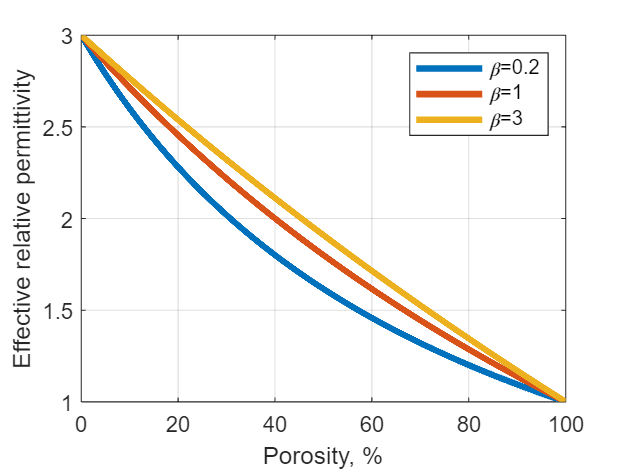

fig = figure;
plot(f_p, epsilon, 'LineWidth',3)
xlabel('Porosity, %')
ylabel("Effective relative permittivity")
grid on
legend('\beta=0.2', '\beta=1', '\beta=3')
xlim([0; 100])

%exportgraphics(fig,'Dielectric_constant.png','Resolution',300)


### Combined graph

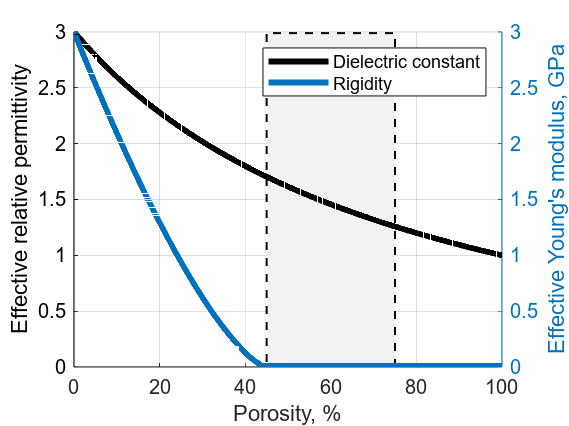

fig = figure;
rectangle('Position',[100*p_c-5,0,30,2.99],'FaceColor',[0.95 0.95 0.95], ...
    'EdgeColor','k', 'LineWidth',1, 'LineStyle','--')
hold on

yyaxis left
plot(f_p, epsilon(1,:), 'LineWidth',3)
xlabel('Porosity, %')
ylabel("Effective relative permittivity")
grid on
xlim([0; 100])

yyaxis right
plot(f_p, E/1e9, 'LineWidth',3)
ylabel("Effective Young's modulus, GPa")
legend('Dielectric constant', 'Rigidity')
hold off

%exportgraphics(fig,'Characteristics.png','Resolution',300)


### Finite elements modeling results

Ball pores

[Data_ball, Beta_ball] = Table_from_txt('Balls.txt');


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Epsilon_ball = epsilon_0*(e_air+Beta_ball*Data_ball.Porosity*(e_air-epsilon_0)+ ...
    Beta_ball*epsilon_0)./(e_air-Data_ball.Porosity*(e_air-epsilon_0)+Beta_ball*epsilon_0);


Horizontal cyliners

[Data_cyl_h, Beta_cyl_h] = Table_from_txt('Horizontal cylinders.txt');


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Epsilon_cyl_h = epsilon_0*(e_air+Beta_cyl_h*Data_cyl_h.Porosity*(e_air-epsilon_0)+ ...
    Beta_cyl_h*epsilon_0)./(e_air-Data_cyl_h.Porosity*(e_air-epsilon_0)+Beta_cyl_h*epsilon_0);


Vertical cyliners

[Data_cyl_v, Beta_cyl_v] = Table_from_txt('Vertical cylinders.txt');


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Epsilon_cyl_v = epsilon_0*(e_air+Beta_cyl_v*Data_cyl_v.Porosity*(e_air-epsilon_0)+ ...
    Beta_cyl_v*epsilon_0)./(e_air-Data_cyl_v.Porosity*(e_air-epsilon_0)+Beta_cyl_v*epsilon_0);


Graph

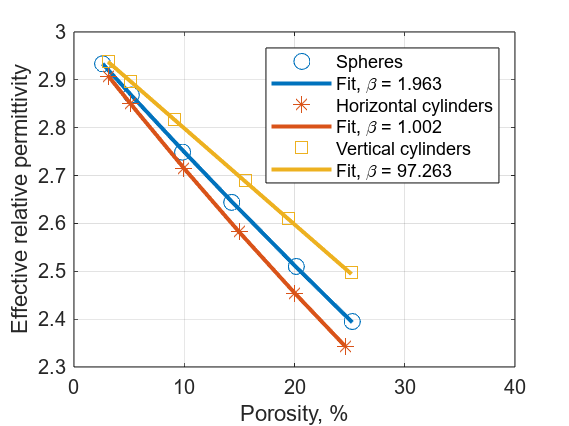

fig = figure;
plot(Data_ball.Porosity*100, Data_ball.Permittivity, 'LineStyle','none', 'Marker','o', 'MarkerSize',8, 'Color',[0, 0.4470, 0.7410])
hold on
plot(Data_ball.Porosity*100, Epsilon_ball, 'LineStyle','-', 'Color',[0, 0.4470, 0.7410], 'LineWidth', 2)

plot(Data_cyl_h.Porosity*100, Data_cyl_h.Permittivity, 'LineStyle','none', 'Marker','*', 'MarkerSize',8, 'Color',[0.8500, 0.3250, 0.0980])
plot(Data_cyl_h.Porosity*100, Epsilon_cyl_h, 'LineStyle','-', 'Color',[0.8500, 0.3250, 0.0980], 'LineWidth', 2)

plot(Data_cyl_v.Porosity*100, Data_cyl_v.Permittivity, 'LineStyle','none', 'Marker','square', 'MarkerSize',8, 'Color',[0.9290, 0.6940, 0.1250])
plot(Data_cyl_v.Porosity*100, Epsilon_cyl_v, 'LineStyle','-', 'Color',[0.9290, 0.6940, 0.1250], 'LineWidth', 2)

xlabel('Porosity, %')
ylabel("Effective relative permittivity")
grid on
legend('Spheres', sprintf('Fit, \\beta = %.3f', Beta_ball), ...
    'Horizontal cylinders', sprintf('Fit, \\beta = %.3f', Beta_cyl_h), ...
    'Vertical cylinders', sprintf('Fit, \\beta = %.3f', Beta_cyl_v))
xlim([0; 40])
hold off
exportgraphics(fig,'FEM fitting.png','Resolution',300)

function [Table, Beta] = Table_from_txt(path)

    fileID = fopen(path,'r');
    Table = fscanf(fileID, '%f');
    Table = transpose(reshape(Table, 2, length(Table)/2));
    Table = Table(:, [2 1]);
    Table(:,1) = Table(:,1)/100;
    Table = array2table(Table, 'VariableNames', {'Porosity', 'Permittivity'});
    Table = sortrows(Table, 'Porosity');

    Beta = Fit_beta(Table);
end

function Beta = Fit_beta(Table)
    
    e_air = 1.00058;
    epsilon_0 = 3;
    f_p = Table.Porosity;
    Permittivity = Table.Permittivity;

    Model = @(Beta, f_p) epsilon_0*(e_air+Beta*f_p*(e_air-epsilon_0)+ ...
    Beta*epsilon_0)./(e_air-f_p*(e_air-epsilon_0)+Beta*epsilon_0);

    Beta = lsqcurvefit(Model, 1, f_p, Permittivity, 0.1, 100);
end